# 6. Functions

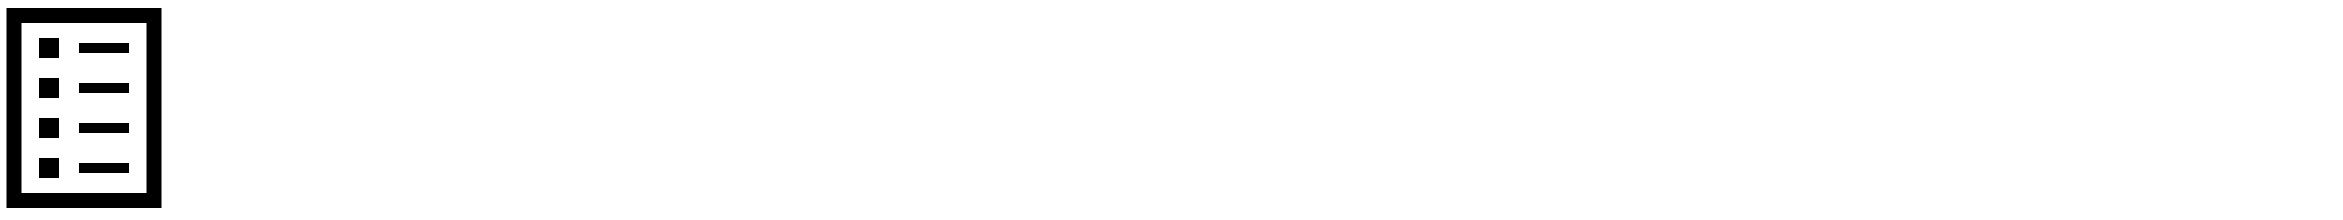

Functions create modular code that can do the same task repeatedly without you having to type out the same code each time. Functions make complex code accessible with a single statement. You also can create your own function, but there are also some are built in to Matlab or in many packages. One built-in function you have already seen is the `disp()` function.

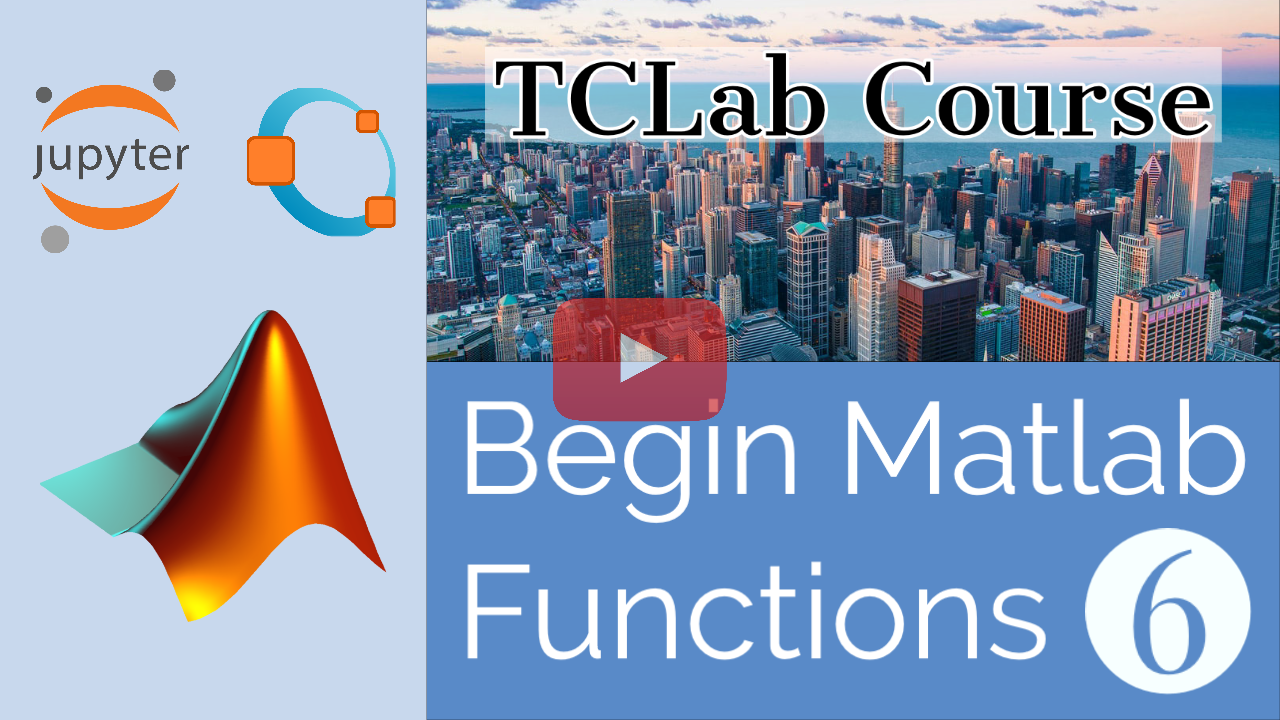

[Click here to watch the video: Matlab 👩‍💻 Functions](https://www.youtube.com/watch?v=Gkgxa05aWec&list=PLLBUgWXdTBDhJJnJW2q2G7e84MZM6dxRN)

### **Create a Function**

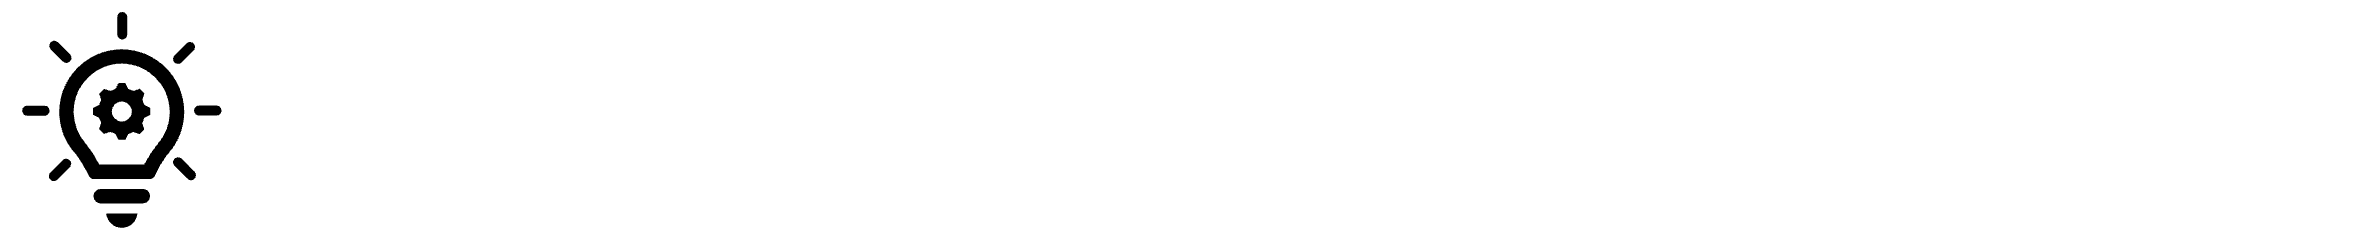

The way to tell the computer you are starting your own function is `function`. It is followed by what is returned from function `y`, and equal sign `=`, the function name `myFunction`, and the input to the function `x`. This function returns the input without changing the value.

`    function` `y ``=` `myFunction``(``x``)`    

`        y` `=` `x``;`

`    end`

### **Option 1: Create a Regular Function**

Before Matlab R2016b, a function `myFunction` was always stored as a separate file as `myFunction.m`. A new option for including functions is to include the function in a script file such as this function that returns `y` as double the input number `x`.

% create function
function y = double_it(x)    
    y = x*2;
end

Try changing the value of the input `4` to another number to test the function result.

double_it(4)

### **Option 2: Create an Anonymous Function**

The same `double_it` function can also be written as a single-line function that is called an `anonymous function`. Anonymous functions are valuable for simple functions that are typically just one line.

double_it = @(x) 2*x;

Try changing the value of the input `8` to another number to test the function result.

double_it(8)

### **Functions Re-use Code**

A display function could be used such as the function `ctemp()` to print the current temperature. This re-uses the `disp` statement so that you don't need to type it out each time for temperatures 1 and 2.

% create the anonymous function
ctemp = @(temperature) disp(['Current temperature: ',num2str(temperature),'°C']);

Suppose that you need to print the temperature every second for 5 seconds. The function can be called many times with different temperature values and no need to repeatedly write out the function code.

% use the function 5 times
ctemp(20.51)
ctemp(22.57)
ctemp(23.32)
ctemp(24.26)
ctemp(25.77)

### **Multiple Inputs**

A function can have more than one value in the function input `()`. The inputs just need to be separated by a comma. If there is no input then you can leave off the `()` or else keep it empty. This function adds together `x` and `y`.

function z = add(x,y)    
    z = x+y;
end
add(2,3)

### **Multiple Outputs**

A function can also have more than one output. The output can be an array of values such as `[z1,z2]` or a single variable that is an array `z`.

function z = multiple(x,y)    \
    z(1) = x+y;    
    z(2) = x^y;
end
z = multiple(2,3)

### **Activity**

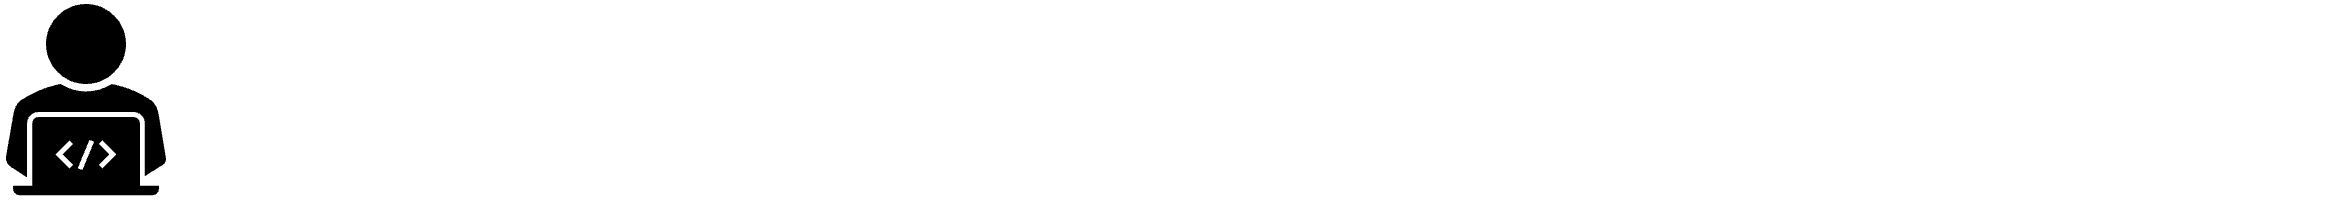

Make a function that divides two values. You can choose the two values or make them a user input. Use the example above for help if you need it.

x = input('x: ');
y = input('y: ');
% create function to evaluate x/y

### TCLab Functions

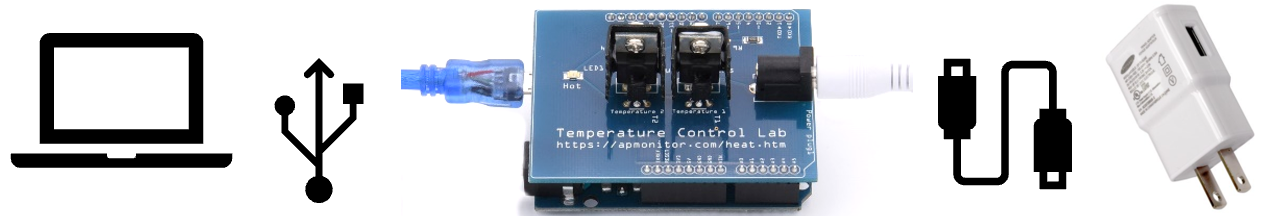

In the last lesson on objects, it mentioned the `lab` object. Objects can have functions that are used with a `.` and then the function name. Using functions, we can change things on our temperature kit values such as **light brightness**, **heater power**, and get **output temperatures**.

***LED***

`lab.LED()` This function will set the light, that is labeled **Hot**, on your TCLab turn on at a certain brightness. If you want the light brightest you would use `lab.LED(100)` and all the way off `lab.LED(0)`.

***Heaters***

`lab.Q1()` or `lab.Q2()` will set the power percentage of heater one or two. Same as the `LED` function, `Q1` is set highest at `lab.Q1(100)` and off at `lab.Q1(0)`. The other heater works the same way, `Q2` is set highest at `lab.Q2(100)` and off at `lab.Q2(0)`

***Temperatures***

`lab.T1` or `lab.T2` gives the current reading of the heater it corresponds to. It will give the values in **Celsius**.

***Disconnecting***

We also use `lab.off()` and `clear lab`at the end of the program to disconnect the kit to make sure it doesn't keep running the heaters. You don't want your heaters on after you've ended the program.

### **Activity**

Turn on the LED to 70% and then turn it off after 10 seconds. Create a `function` to turn on the LED, print out the percent that it is on, and pause for 1 second. Call the function multiple times to verify that it works.

Create a new function that adds to the prior function by also turning on the heater, `lab.Q1`, to the same level as the LED. In addition to printing the level of the heater and LED have the function return temperatures 1 and 2.

Make sure to disconnect the heaters after you finish. If the heaters don't turn off because of a bug in your code, clear the `lab` object with `clear lab`. If you get errors when you run your code, check out the **TCLab Help** IPython notebook for common errors or search the [Frequently Asked Questions for Troubleshooting](https://apmonitor.com/pdc/index.php/Main/ArduinoSetup). You can also read the error descriptions Jupyter gives you below your code to diagnose the problem.